# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: ejercicio 03 - Clasificación de Digitos Usando HOG Features

Este ejemplo muestra cómo clasificar dígitos utilizando características HOG y un clasificador SVM multiclase.

La clasificación de objetos es una tarea importante en muchas aplicaciones de visión por ordenador, incluyendo la vigilancia, la seguridad en el automóvil y la recuperación de imágenes. Independientemente del tipo de objeto que se clasifique, el procedimiento básico para crear un clasificador de objetos es el siguiente

- Adquirir un conjunto de datos etiquetados con imágenes del objeto deseado.

- Dividir el conjunto de datos en un conjunto de entrenamiento y un conjunto de test.

- Entrenar el clasificador utilizando las características extraídas del conjunto de entrenamiento.

- Probar el clasificador utilizando las características extraídas del conjunto de test.

Para ilustrarlo, este ejemplo muestra cómo clasificar dígitos numéricos utilizando características HOG (Histograma de Gradiente Orientado) y un clasificador multiclase SVM (Support Vector Machine). Este tipo de clasificación se utiliza a menudo en muchas aplicaciones de reconocimiento óptico de caracteres (OCR).

El ejemplo utiliza la función `fitcecoc` de la `Statistics and Machine Learning Toolbox™` y la función `extractHOGFeatures` de la `Computer Vision Toolbox™`. (Estas toolbox deberían estar instaladas)

clc;
clear all;
close all;

## 1) Base de datos de dígitos

Para el entrenamiento se utilizan imágenes de dígitos sintéticos. Cada una de las imágenes de entrenamiento contiene un dígito rodeado de otros dígitos, lo que imita cómo se ven normalmente los dígitos juntos. El uso de imágenes sintéticas es conveniente y permite la creación de una variedad de muestras de entrenamiento sin tener que recogerlas manualmente. Para las pruebas, se utilizan escaneos de dígitos escritos a mano para validar el rendimiento del clasificador con datos diferentes a los de entrenamiento. Aunque no es el conjunto de datos más representativo, hay suficientes datos para entrenar y probar un clasificador, y mostrar la viabilidad del enfoque.

Se utiliza `countEachLabel` para tabular el número de imágenes asociadas a cada etiqueta. En este ejemplo, el conjunto de entrenamiento consta de 101 imágenes para cada uno de los 10 dígitos (1010 imágenes). El conjunto de test consta de 12 imágenes por dígito (120 imágenes).

% |imageDatastore| recursively scans the directory tree containing the
% images. Folder names are automatically used as labels for each image.
trainingSet = imageDatastore('digits/synthetic/','IncludeSubfolders',true,'LabelSource','foldernames');
testSet     = imageDatastore('digits/handwritten/','IncludeSubfolders',true,'LabelSource','foldernames');

countEachLabel(trainingSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       101 
      1       101 
      2       101 
      3       101 
      4       101 
      5       101 
      6       101 
      7       101 
      8       101 
      9       101 


countEachLabel(testSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       12  
      1       12  
      2       12  
      3       12  
      4       12  
      5       12  
      6       12  
      7       12  
      8       12  
      9       12  


## 2) HOG Features

Los datos utilizados para entrenar el clasificador son vectores de características HOG extraídos de las imágenes de entrenamiento. Por lo tanto, es importante asegurarse de que el vector de características HOG codifica la cantidad correcta de información sobre el objeto. La función `extractHOGFeatures` devuelve un resultado de visualización que puede ayudar a formar alguna intuición sobre lo que significa la "cantidad correcta de información". Variando el parámetro del tamaño de la celda HOG (`cellSize)` y visualizando el resultado, se puede ver el efecto que tiene el parámetro del tamaño de la celda en la cantidad de información de forma codificada en el vector de características.

Un valor de comprosimo del tamaño de celda (`cellSize) es [4 4]`, este tamaño codifica suficiente información espacial para identificar visualmente la forma de un dígito al tiempo que limita el número de dimensiones del vector de características HOG.

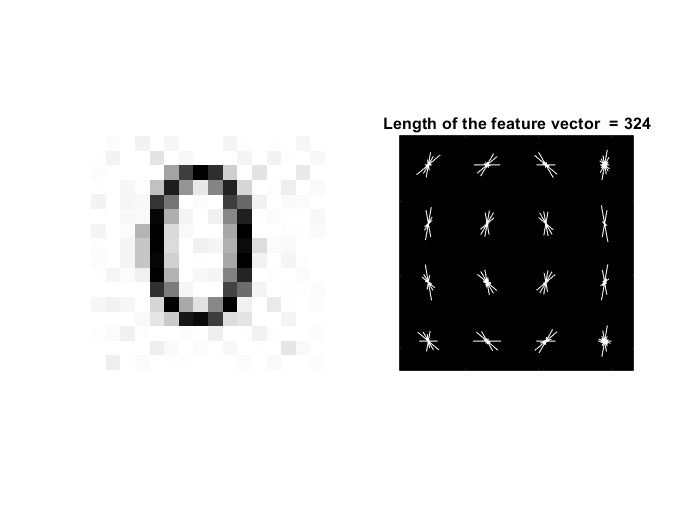

% Loop over the trainingSet and extract HOG features from each image. A similar procedure will be used to extract features from the testSet.

% tamaño de la celda HOG 
cellSize = [4 4];

% se lee la primera imagen del dataset
img = readimage(trainingSet,1);

% Sólo se hace una vez. Extract HOG features and HOG visualization
[hog_feature_vec, hog_valid_points] = extractHOGFeatures(img,'CellSize',cellSize);
hogFeatureSize = length(hog_feature_vec);
        
% Número de elementos de la matriz
numImagesTrain = numel(trainingSet.Files);
trainingFeatures = zeros(numImagesTrain,hogFeatureSize,'single');

figure;
subplot(1,2,1);
imshow(img); 
subplot(1,2,2);
plot(hog_valid_points);
title({['Length of the feature vector  = ' num2str(length(hog_feature_vec))]});

## 3) Extracción de caracterísitcas. 

Comience por extraer las características HOG del conjunto de entrenamiento. Estas características se utilizarán para entrenar el clasificador.

for i = 1:numImagesTrain

    img = readimage(trainingSet,i);
    
    img = rgb2gray(img);
    
    % Apply pre-processing steps
    img = imbinarize(img);
%     imshow(img,[]);
%     drawnow;
    trainingFeatures(i, :) = extractHOGFeatures(img,'CellSize',cellSize);  
end

% Get labels for each image.
trainingLabels = trainingSet.Labels;

## 4) Entrenamiento del Clasificador de dígitos

La clasificación de dígitos es un problema de clasificación multiclase, en el que hay que clasificar una imagen en una de las diez clases de dígitos posibles. En este ejemplo, la función `fitcecoc` de la Toolbox™ `Statistics and Machine Learning `se utiliza para crear un clasificador multiclase utilizando SVMs binarias.

A continuación, se entrena un clasificador utilizando las características extraídas. 

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.
classifier = fitcecoc(trainingFeatures, trainingLabels,"Coding","onevsone");

## Se pide:

- Evalúe el clasificador utilizando imágenes del conjunto de test y genere una matriz de confusión para cuantificar la precisión del clasificador, calculando la exactitud del clasificador como `(accuracy = aciertos/total)` . Al igual que en el caso del entrenamiento, primero se deben extraen las características HOG de las imágenes de test usando la función `extractHOGFeatures()`. Estas características se utilizarán después para hacer predicciones con la función `predict()` y utilizando el clasificador entrenado.

- Vuelva entrenar el clasificador con un conjunto de datos más representativo, el dataset de MNIST ([http://yann.lecun.com/exdb/mnist/](http://yann.lecun.com/exdb/mnist/)), que contienen miles de caracteres escritos a mano. Descargue el conjunto de entrenamiento y test, y sus respectivas etiquetas, utilizando los siguientes enlaces:

[http://yann.lecun.com/exdb/mnist/train-images-idx3-ubyte.gz](http://yann.lecun.com/exdb/mnist/train-images-idx3-ubyte.gz) `training set (60000 imágenes)`

[http://yann.lecun.com/exdb/mnist/train-labels-idx1-ubyte.gz](http://yann.lecun.com/exdb/mnist/train-labels-idx1-ubyte.gz)` training set labels`

[http://yann.lecun.com/exdb/mnist/t10k-images-idx3-ubyte.gz](http://yann.lecun.com/exdb/mnist/t10k-images-idx3-ubyte.gz)` test set (10000 imágenes)`

[http://yann.lecun.com/exdb/mnist/t10k-labels-idx1-ubyte.gz](http://yann.lecun.com/exdb/mnist/t10k-labels-idx1-ubyte.gz)` test set labels`

                Descomprima los fichero y lealos con la función `readMNIST` (por ejemplo con la siguiente instrucción se leen las 100 primeras imágenes y sus correspondientes etiquetas del  conjunto de datos de test)

`               [imgs labels] = readMNIST('t10k-images.idx3-ubyte', 't10k-labels.idx1-ubyte', 100, 0)`